#### Graph Solution to Question 


$$f_n \left(x\right)=\left\lbrace \begin{array}{ll}
cx^n \left(1-x^n \right), & 0\le x\le 1\\
0, & \textrm{otherwise}
\end{array}\right.$$


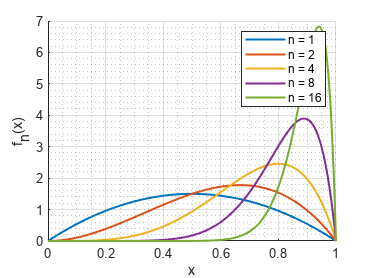

% Define the values of n and x
n_values = [1, 2, 4, 8, 16];
x_values = linspace(0, 1, 1000); % 1000 points between 0 and 1

% Define the function fn(x) and calculate the value of c for each value of n
c_values = zeros(1, length(n_values));
for i = 1:length(n_values)
    n = n_values(i);
    syms x f(x);
    f(x) = x^n*(1 - x);
    c_values(i) = 1/int(f, x, 0, 1); % calculate the value of c
end

% Define the function fn(x) for each value of n
fn_values = zeros(length(n_values), length(x_values));
for i = 1:length(n_values)
    n = n_values(i);
    c = c_values(i);
    fn_values(i,:) = c*x_values.^n.*(1 - x_values);
end

% Plot the graph of fn(x) for each value of n
figure;
hold on;
for i = 1:length(n_values)
    plot(x_values, fn_values(i,:), 'LineWidth', 1.5);
end
xlabel('x');
ylabel('f_n(x)');
legend('n = 1', 'n = 2', 'n = 4', 'n = 8', 'n = 16');
grid on; grid minor;
hold off;

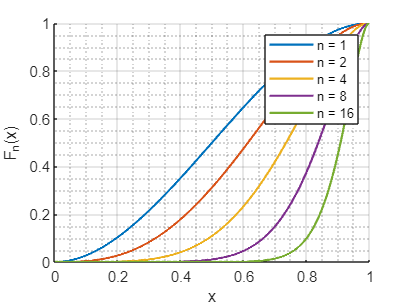



% Define the distribution function Fn(x) for each value of n
Fn_values = zeros(length(n_values), length(x_values));
for i = 1:length(n_values)
    n = n_values(i);
    c = c_values(i);
    Fn_values(i,:) = cumsum(fn_values(i,:))*(1/(length(x_values)-1));
end

% Plot the graph of Fn(x) for each value of n
figure;
hold on;
for i = 1:length(n_values)
    plot(x_values, Fn_values(i,:), 'LineWidth', 1.5);
end
xlabel('x');
ylabel('F_n(x)');
legend('n = 1', 'n = 2', 'n = 4', 'n = 8', 'n = 16');
grid on; grid minor;
hold off;